x = x0;

tsim = 10;
nsim = round(tsim / Ts); % Simulation steps

x_log = zeros(nx, nsim); % States
u_log = zeros(nu, nsim); % Inputs
x_pre = zeros(nx, nsim, N); % State predictions over horizon at each step
tt_log = linspace(0, tsim, nsim);
tt_pre = zeros(nsim, N);
run_times = zeros(nsim, 1);

nlDynamics = true;

for i = 1 : nsim
    % solveMPC(x, xr);
    [x_res, y, status_val, iter, run_time] = emosqp('solve'); 

    ctrl = x_res((N+1)*nx+1:(N+1)*nx+nu);
    run_times(i) = run_time;

    % Simulate response
    if nlDynamics
        x = x + xUe;
        x = model_nlRK4(f_comb_nl_handle, x, ctrl + U_e_vec, Ts);
        x = x - xUe;
    else
        x = Ad*x + Bd*ctrl;
    end

    % Update initial state
    l(1:nx) = -x;
    u(1:nx) = -x;

    % Update cost for variable xr
    q = [repmat(-Q*xr, N, 1); -QN*xr; zeros(N*nu, 1)];

    emosqp('update_bounds', l, u);
    emosqp('update_lin_cost', q);

    % Log
    x_log(:,i) = x;
    u_log(:,i) = ctrl;
    x_pre(:, i, :) = reshape(x_res(nx+1:(N+1)*nx), [nx, N]);
    tt_pre(i, :) = linspace(tt_log(i), tt_log(i)+Ts*N, N);
end

% Get mean runtime;
mean(run_times)

ans = 0.0100

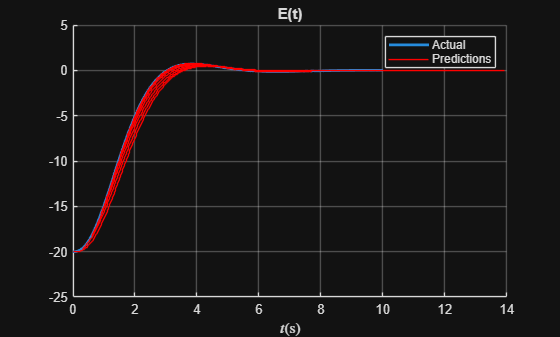

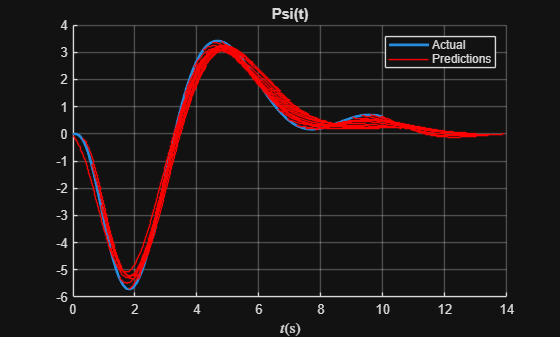

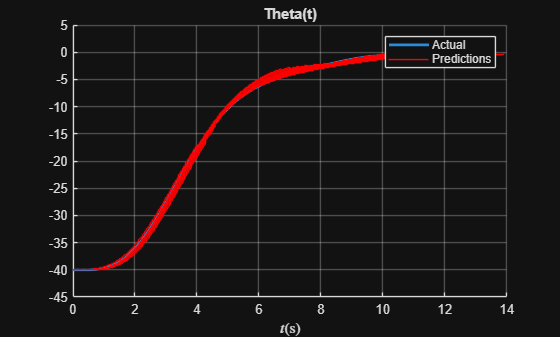


x_pre_samples = 1:20:length(tt_log); % Display predictions at intervals

for c = 1:3
    figure
    hold on
    plotTimeseries(tt_log, (180/3.14)*x_log(c, :), 'Title', char(X_rb(c)))
    % plotTimeseries(tt_log, x_log(c, :), 'Title', 'Positions')
    stairs(tt_pre(x_pre_samples, :)', (180/3.14)*squeeze(x_pre(c, x_pre_samples, :))', 'r')
    hold off
    legend('Actual', 'Predictions')
end

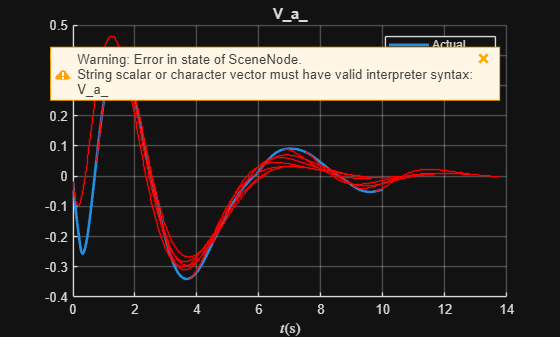

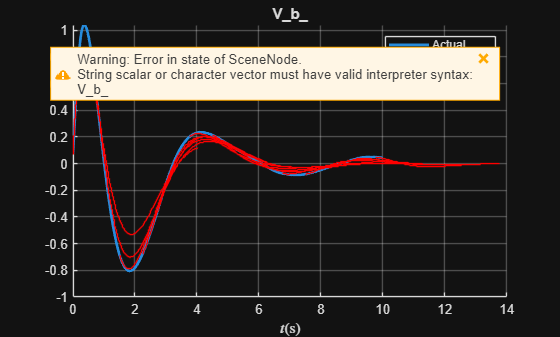

f_pre_samples = 1:50:length(tt_log); % Display predictions at intervals
for c = 7:8
    figure
    hold on
    plotTimeseries(tt_log, x_log(c, :), 'Title', char(X_comb(c)))
    % plotTimeseries(tt_log, x_log(c, :), 'Title', 'Positions')
    stairs(tt_pre(f_pre_samples, :)', squeeze(x_pre(c, f_pre_samples, :))', 'r')
    hold off
    legend('Actual', 'Predictions')
end

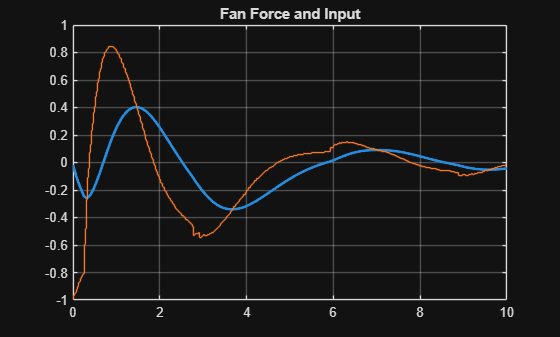

figure
plot(tt_log, x_log(7, :), 'LineWidth', 2)
hold on
stairs(tt_log, u_log(1, :))
title('Fan Force and Input')
grid on
hold off

% plotTimeseries(tt_log, x_log(1:3, :), 'Title', 'Positions')
% plotTimeseries(tt_log, x_log(7:8, :) + F_e_real, 'Title', 'Fan Forces')
% plotTimeseries(tt_log, u_log, 'Title', 'Inputs', 'LineType', 'stairs')